# **TRABAJO DE INVESTIGACIÓN TESIS (NO UNIFORME)**

(Daniel Rojas, Sebastian Mejia, Jhon Smith, Andres Felipe)

% Region: Bello
% Parameters: mu_h, mu_m, gamma, z, beta_hm, beta_mh, r, C, v_h, v_m
pars = [0.00145, 0.3848,0.9776,5.9052,0.9628,0.8030,13.9406,0.0182,4.78e3,1.58e4];
% Temporal Domain
domain = [1, 50];  % From t=1 to t=100
% Set Initial conditions
initial_conditions = [80, 20, 800, 200, 0]; 
names = {'M_S','M_I','H_s','H_I','H_R','mu_h','mu_m','gamma','z','beta_hm','beta_mh','r','C','v_h','v_m'}; % Factors names
out_names = {'M_s(t)','M_I(t)','H_s(t)','H_I(t)','H_r(t)','Ihum'}; % Output Names
factors = [initial_conditions,pars];
% Ranges
rpars = [0 0.6;0 1;0.1 1; 0 30;0 1;0 1;0 100;0 2e3;0 1e2;0 1e2];
rconds = [80 80; 0 70; 800 800; 0 300; 0 0];
range = [rconds;rpars];
% Gsua Toolbox implementation
TU = gsua_dataprep('SIR1',range,'domain',domain,'out_names',out_names,'names',names);

Setting environment to work with user-defined function


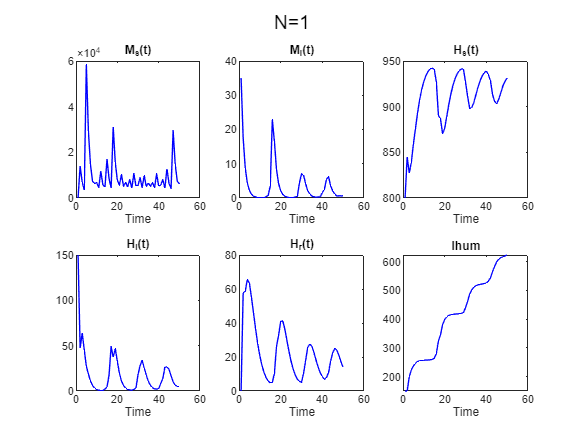

y=gsua_eval(TU.Nominal,TU);

TU.Properties.CustomProperties.output = 6;

# **Importe de datos**

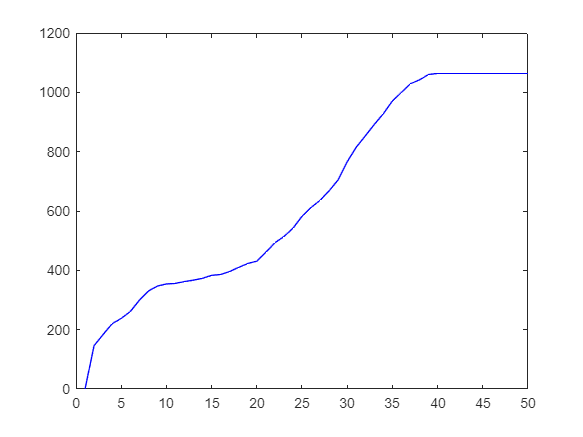

load NoUniforme2_2.mat
close all
xdata1=1:50;
dataY1=Hi_No_uniforme(xdata1);
plot(dataY1,color='blue');

M=gsua_dmatrix(TU,1000);
TU

TU = 12x2 table
                  Range       Nominal
               ___________    _______

    M_I          0      70       35  
    H_I          0     300      150  
    mu_h         0     0.6      0.3  
    mu_m         0       1      0.5  
    gamma      0.1       1     0.55  
    z            0      30       15  
    beta_hm      0       1      0.5  
    beta_mh      0       1      0.5  
    r            0     100       50  
    C            0    2000     1000  
    v_h          0     100       50  
    v_m          0     100       50  


# **Análisis de incertidumbre**

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 18:13:30
Number of simulations: 1000


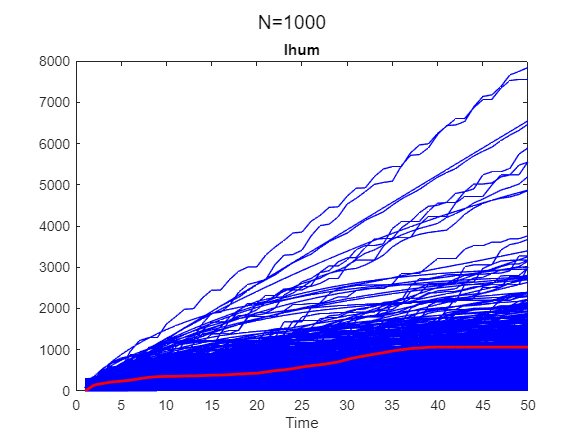

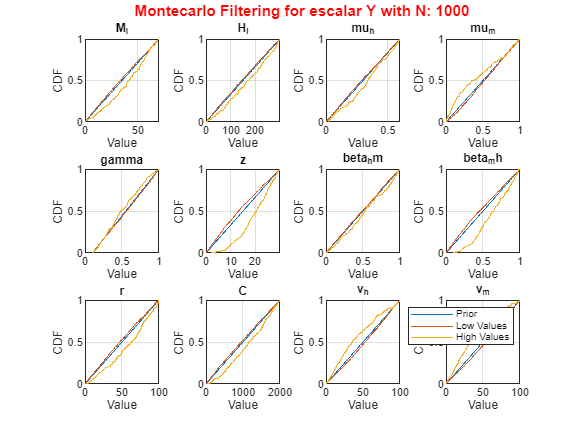

close all
gsua_ua(M,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

# **Estimación de parámetros con Serie de tiempo (Diferente de 1)**

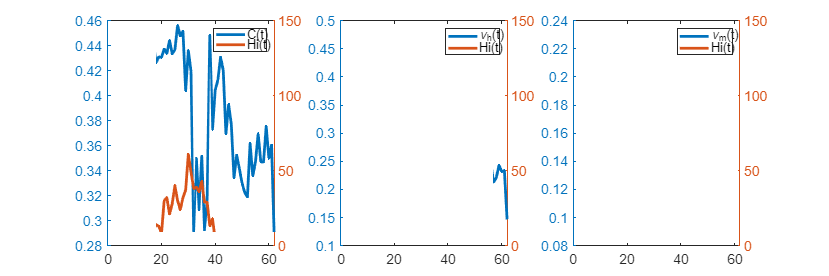

% SERIE DE TIEMPOS PARA UNIFORME
map1 = matrix_Map_No_Uni{1};
map2 = matrix_Map_No_Uni{2};
map3 = matrix_Map_No_Uni{3};

H1 = map1(2:end, 3);
H2 = map2(2:end, 3);
V = map3(2:end, 3:end);
result_matrix = zeros(1, size(V, 2));
H = max([H1,H2],[],2);
H_ponderador = H/sum(H);
V_ponderador = V./sum(V);
nuH=sum(V.*H_ponderador);
nuM=sum(H.*V_ponderador);
Ct=mean(V(H~=0,:));
Hi_noAcc=Hi_No_uniforme-[0,Hi_No_uniforme(1:end-1)];
figure('Position',[10 10 1200 400])
clf
subplot(1,3,1)
yyaxis left
plot(Ct,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"C(t)","Hi(t)"})
subplot(1,3,2)
yyaxis left
plot(nuH,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_h(t)","Hi(t)"})
subplot(1,3,3)
yyaxis left
plot(nuM,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_m(t)","Hi(t)"})

**Vincular la serie de tiempo al modelo**

Preparar la estructura para ingresar al modelo la serie de tiempo

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 18:13:39
Number of simulations: 1000


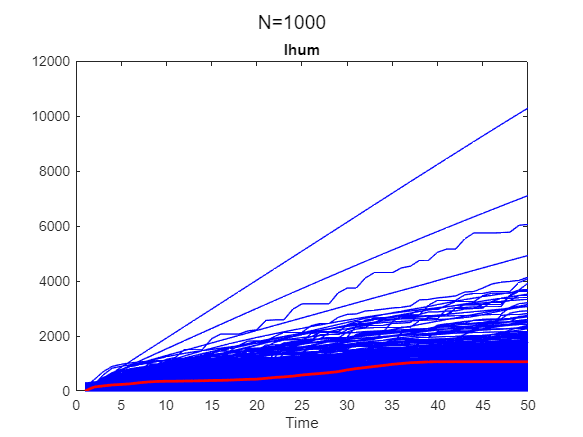

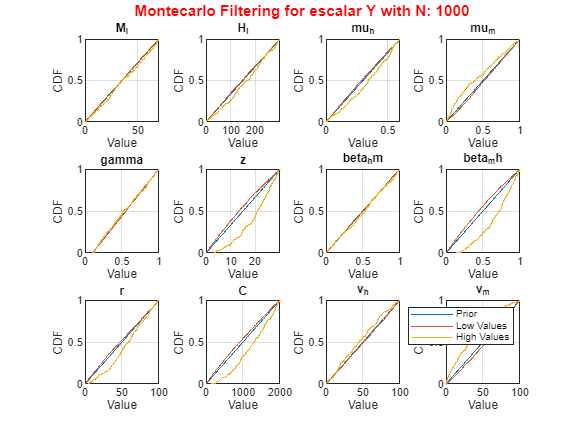

dataIn=struct();
dataIn.timeSer=Ct;
dataIn.Nuh=nuH;
dataIn.Num=nuM;
dataIn.action=2;

TU.Properties.CustomProperties.copt=dataIn;%Se asigna la serie de tiempo al modelo
close all
gsua_ua(M,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

# **Estimación de Parametros**

solver='fmincon';%this is the default solver
opt=optimoptions('fmincon','UseParallel',false,'MaxIterations',5e4,'MaxFunctionEvaluations',1e5);%configure optimizer
nestim=1000;
resT=zeros(1,nestim);
IPT=zeros(size(TU,1),nestim);
estimations=zeros(size(TU,1),nestim);

parfor i=1:nestim
    [T_e,res,IP] =gsua_pe(TU,xdata1,dataY1,'N',1,'solver',solver,'Show','off','opt',opt,'margin',0.3);
    IPT(:,i)=IP;
    resT(i)=res;
    estimations(:,i)=T_e.Estfmincon;
    clc
    if mod(i,30)==0
        disp("Progress "+num2str(round(nestim/i*100)))
    end
end

Generating a valid matrix for estimations
Estimation 1

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Progress: 100%
Estimated processing time (h:m:s): 0:0:22
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:22
Estima


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 18:31:1
Number of simulations: 1
Generating a valid matrix for estimations
Es


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.

Progress: 100%
Estimated processing time (h:m:s): 0:1:16
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:1:16
Estimated stop time (h:m:s): 19:26:16
Number of simulations: 1
Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the

%[T_e,res,IP] =gsua_pe(TU,xdata1,dataY1,'N',nestim,'solver',solver,'Show','on','opt',opt,'margin',0.3);
[sortedResT,idx]=sort(resT,'ascend');
sortedEstims=estimations(:,idx);
IPT=IPT(:,idx);

save("ALEPHCambio2ResultsEstims1000NU2_SA.mat","sortedResT","sortedEstims","IPT");%SA stands for serie activa

# **Análisis de identificabilidad **

clear;clc;close all

% Region: Bello
% Parameters: mu_h, mu_m, gamma, z, beta_hm, beta_mh, r, C, v_h, v_m
pars = [0.00145, 0.3848,0.9776,5.9052,0.9628,0.8030,13.9406,0.0182,4.78e3,1.58e4];
% Temporal Domain
domain = [1, 50];  % From t=1 to t=100
% Set Initial conditions
initial_conditions = [80, 20, 800, 200, 0]; 
names = {'M_S','M_I','H_s','H_I','H_R','mu_h','mu_m','gamma','z','beta_hm','beta_mh','r','C','v_h','v_m'}; % Factors names
out_names = {'M_s(t)','M_I(t)','H_s(t)','H_I(t)','H_r(t)','Ihum'}; % Output Names
factors = [initial_conditions,pars];
% Ranges
rpars = [0 0.6;0 1;0.1 1; 0 30;0 1;0 1;0 100;0 2e3;0 1e2;0 1e2];
rconds = [80 80; 0 70; 800 800; 0 300; 0 0];
range = [rconds;rpars];
% Gsua Toolbox implementation
TU = gsua_dataprep('SIR1',range,'domain',domain,'out_names',out_names,'names',names);

Setting environment to work with user-defined function


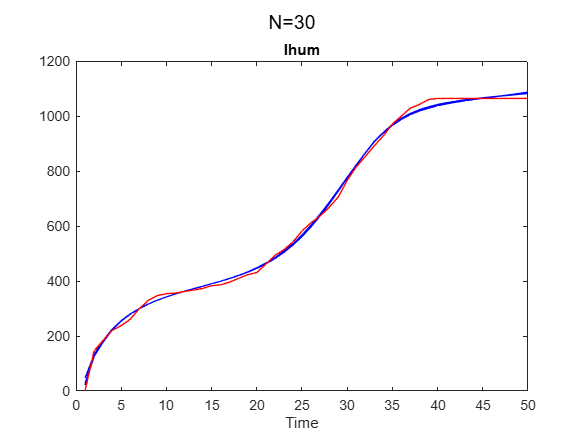

load ALEPHCambio2ResultsEstims1000NU2_SA
load NoUniforme2_2.mat

% SERIE DE TIEMPOS PARA UNIFORME
map1 = matrix_Map_No_Uni{1};
map2 = matrix_Map_No_Uni{2};
map3 = matrix_Map_No_Uni{3};

H1 = map1(2:end, 3);
H2 = map2(2:end, 3);
V = map3(2:end, 3:end);
result_matrix = zeros(1, size(V, 2));
H = max([H1,H2],[],2);
H_ponderador = H/sum(H);
V_ponderador = V./sum(V);
nuH=sum(V.*H_ponderador);
nuM=sum(H.*V_ponderador);
Ct=mean(V(H~=0,:));
Hi_noAcc=Hi_No_uniforme-[0,Hi_No_uniforme(1:end-1)];
figure('Position',[10 10 1200 400])
clf
subplot(1,3,1)
yyaxis left
plot(Ct,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"C(t)","Hi(t)"})
subplot(1,3,2)
yyaxis left
plot(nuH,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_h(t)","Hi(t)"})
subplot(1,3,3)
yyaxis left
plot(nuM,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_m(t)","Hi(t)"})

dataIn=struct();
dataIn.timeSer=Ct;
dataIn.Nuh=nuH;
dataIn.Num=nuM;
dataIn.action=2;

TU.Properties.CustomProperties.copt=dataIn;%Se asigna la serie de tiempo al modelo
TU.Properties.CustomProperties.output = 6;

xdata1=1:50;
dataY1=Hi_No_uniforme(xdata1);
thr=min(sortedResT)*2;
TU.Estims=sortedEstims;
close all
selector=sum(sortedResT<thr);
figure(1)
gsua_eval(TU.Estims(:,1:selector),TU,xdata1,dataY1);

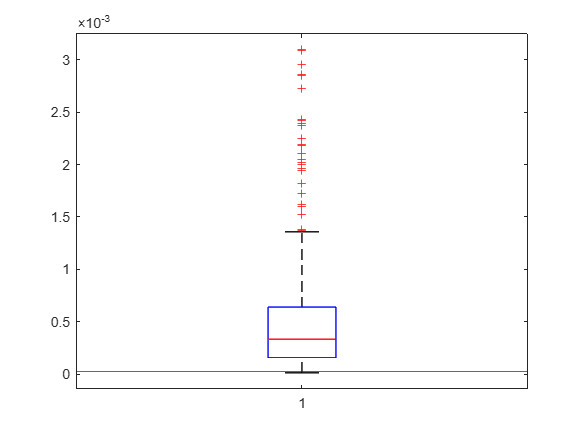

figure(2)
clf
boxplot(sortedResT(1:200))
hold on
yline(thr)

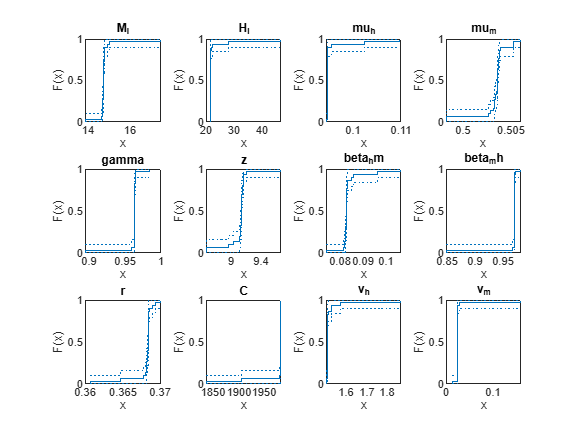

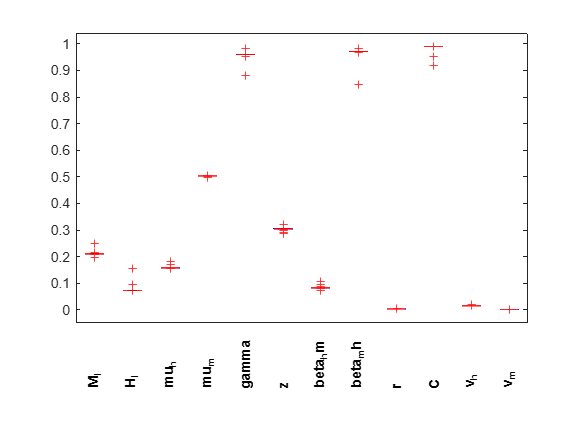

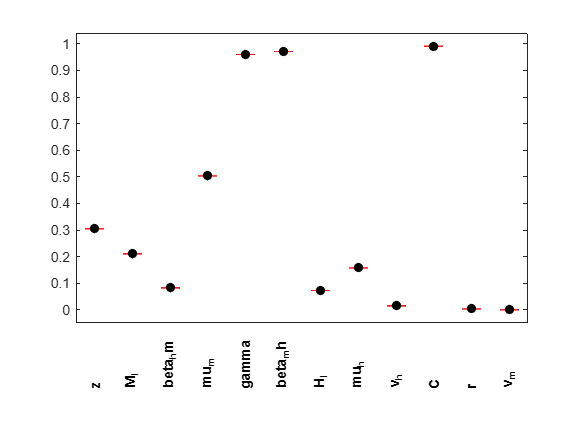

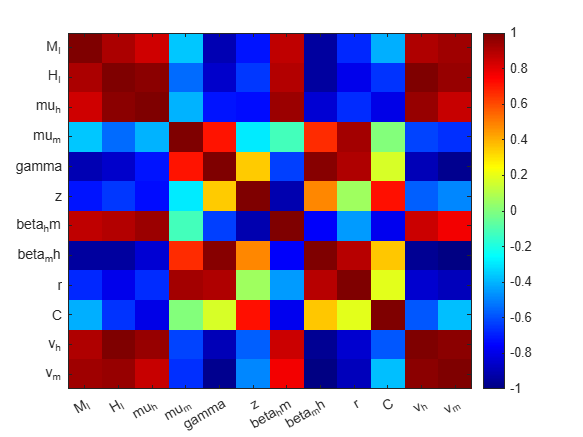

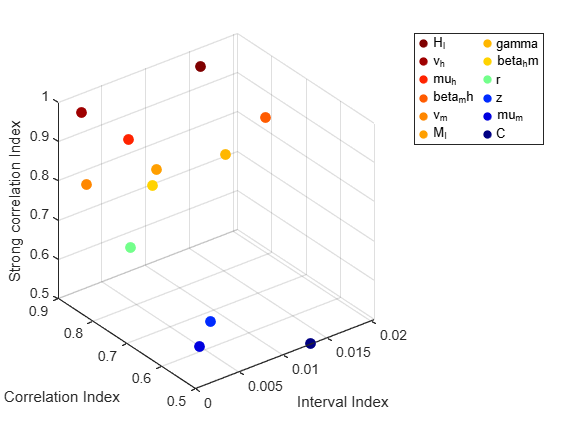

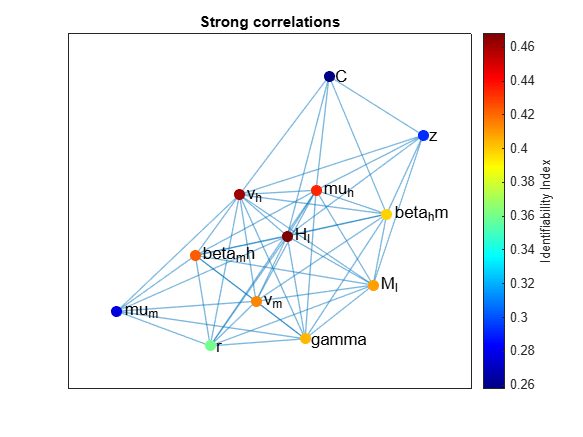

T = 12x5 table
                      Range            Nominal        Estims            Est         index 
               ____________________    ________    _____________    ___________    _______

    M_I          14.504      14.983      14.744    1x1000 double    1x30 double    0.40901
    H_I          19.415      23.653      21.534    1x1000 double    1x30 double    0.46849
    mu_h       0.093346    0.096057    0.094702    1x1000 double    1x30 double    0.43411
    mu_m        0.50288     0.50426     0.50357    1x1000 double    1x30 double    0.27742
    gamma        0.9575     0.96955     0.96352    1x1000 double    1x30 double    0.40386
    z            9.0649      9.2098      9.1373    1x1000 double    1x30 do

close all
Tia=gsua_ia(TU,TU.Estims(:,1:selector),true,false,true);

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 22:43:54
Number of simulations: 1000


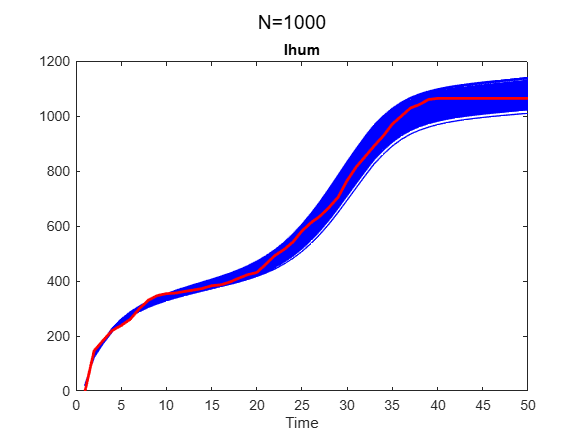

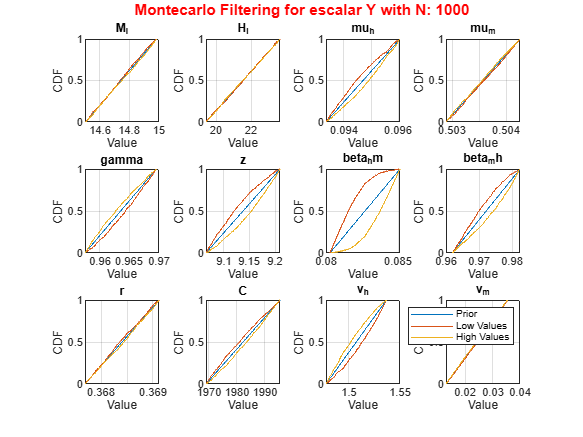

close all
Mia=gsua_dmatrix(Tia,1e3);
gsua_ua(Mia,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

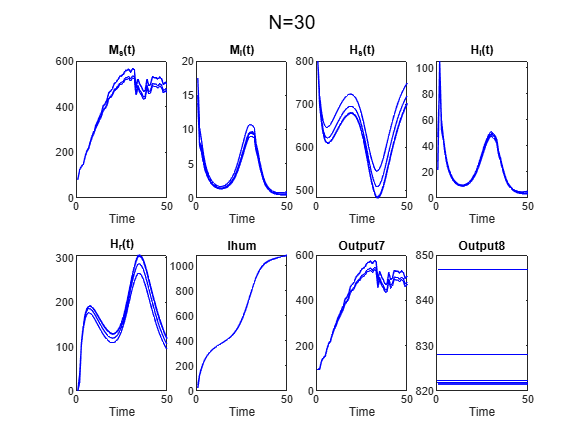

close all
TU.Properties.CustomProperties.output=1:8;
gsua_eval(TU.Estims(:,1:selector),TU,xdata1);

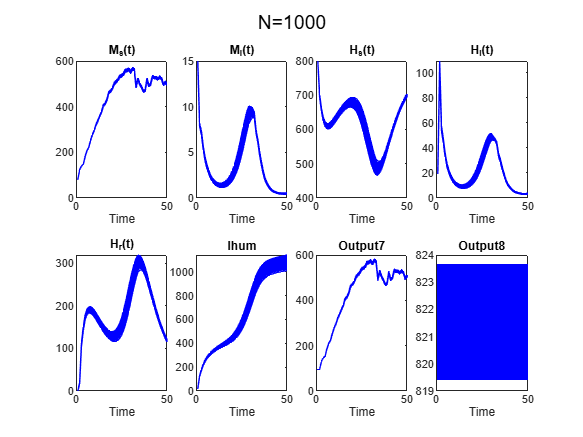

gsua_eval(Mia',TU,xdata1);

TU.Properties.CustomProperties.output=1:8;